clear
clc
close all

%Generate Data:

t = linspace(0, 2*pi, 100);
x = 5*cos(t);
y = 2*sin(t);
z = t;

%Draw/Render the Scenario:

figh = figure

figh =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


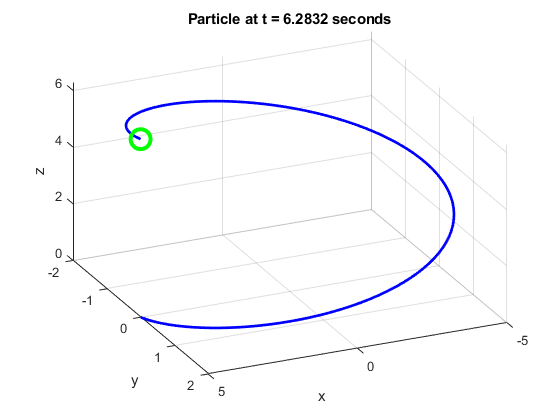


for k=1:length(t)
    %Wipe the slate clean
    clf
    
    %Extract data at current time t
    t_k = t(k);
    x_k = x(k);
    y_k = y(k);
    z_k = z(k);
    
    %Plot current location of the particle
    plot3(x_k, y_k, z_k, 'go', 'LineWidth', 3, 'MarkerSize', 15)
    
    %Plot entire trajectory
    hold on
    plot3(x, y, z, 'b-', 'LineWidth', 2)
    
    %Decorate plot
    grid on
    xlabel('x')
    ylabel('y')
    zlabel('z')
    title(['Particle at t = ', num2str(t_k), ' seconds'])
    view([30+20*t_k 35])
    
    %drawnow
    movieVector(k) = getframe(figh, [10 10 520 400]);
end


%Save the movie:;
myWriter = VideoWriter('curve', 'MPEG-4')

myWriter =   VideoWriter

    General Properties:

       Filename:                 'curve.mp4'
       Path:                     'C:\Users\Sam\Desktop\Code\MATLAB\MATLAB_Learning'
       FileFormat:               'mp4'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                30
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'H.264'
       Quality:                  75

  Methods


myWriter.FrameRate = 20;

open(myWriter);
writeVideo(myWriter, movieVector);
close(myWriter);